filename = '/MATLAB Drive/BTP/CleanProcessed with Peer and External Routing 20240318 Split.xlsx';
data = readtable(filename);

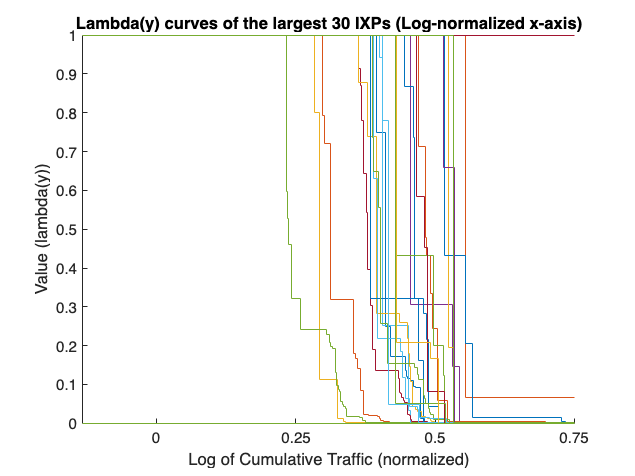

unique_ixps = unique(data.ix_id);
colors = lines(numel(unique_ixps)); % Generate distinct colors for each IXP

figure; % Create a new figure
hold on; % Hold on to plot all IXPs on the same figure

% A small constant to avoid taking the log of zero
epsilon = 1e-6;

for i = 1:length(unique_ixps)
    ixp_id = unique_ixps(i);
    
    % Extract data for the current IXP
    ixp_data = data(data.ix_id == ixp_id, :);
    
    % Sort by d_ij in descending order and calculate the cumulative sum of b_ij
    [sorted_d_ij, sortIdx] = sort(ixp_data.d_ij, 'descend');
    sorted_b_ij = ixp_data.b_ij_split(sortIdx);
    cumsum_b_ij = cumsum(sorted_b_ij);
    
    % Normalize the cumulative sum of b_ij
    normalized_cumsum_b_ij = cumsum_b_ij / max(cumsum_b_ij);
    
    % Normalize the d_ij values and apply a logarithmic transformation
    normalized_sorted_d_ij = log(sorted_d_ij / max(sorted_d_ij) + epsilon);
    
    % Add initial points to start the curve at the beginning
    normalized_cumsum_b_ij = [0; normalized_cumsum_b_ij];
    normalized_sorted_d_ij = [min(normalized_sorted_d_ij); normalized_sorted_d_ij];
    
    % Plot the non-increasing step function
    stairs(normalized_sorted_d_ij, normalized_cumsum_b_ij, 'Color', colors(i, :));
end

% Normalize the d_ij values to be between eps and 1
    normalized_d_ij = (data.d_ij - min(data.d_ij)) / (max(data.d_ij) - min(data.d_ij));
    normalized_d_ij = normalized_d_ij * (1 - eps) + eps;

    % Apply logarithmic transformation
    log_normalized_d_ij = log10(normalized_d_ij);

    % Generate the plot using the logarithmically transformed data
    % ... [code to generate the stairs plot using log_normalized_d_ij] ...

    % Set custom tick marks to represent the normalized values
    xticks = linspace(min(log_normalized_d_ij), max(log_normalized_d_ij), 5);
    xticklabels = linspace(0, 1, 5);

    % Apply the custom tick marks and labels
    set(gca, 'XTick', xticks, 'XTickLabel', arrayfun(@num2str, xticklabels, 'UniformOutput', false));

hold off;
xlabel('Log of Cumulative Traffic (normalized)');
ylabel('Value (lambda(y))');
title('Lambda(y) curves of the largest 30 IXPs (Log-normalized x-axis)');
% Set the x-axis limits based on the transformed values
xlim([min(normalized_sorted_d_ij), 0]);
ylim([0, 1]);

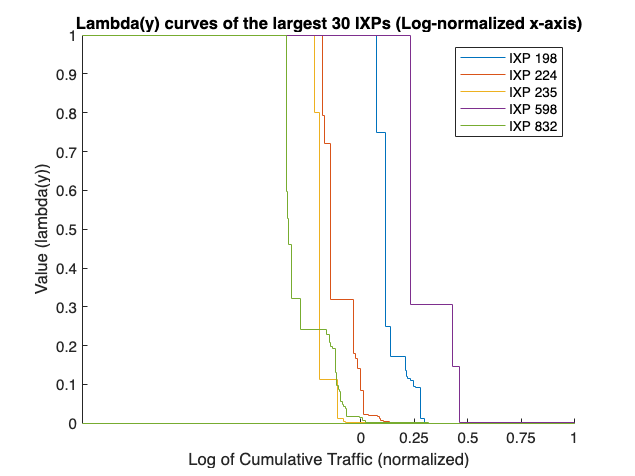

unique_ixps = unique(data.ix_id);
colors = lines(numel(unique_ixps)); % Generate distinct colors for each IXP

figure; % Create a new figure
hold on; % Hold on to plot all IXPs on the same figure


% A small constant to avoid taking the log of zero
epsilon = 1e-6;

legend_labels = {}; % Initialize legend labels

for i = 1:5
    ixp_id = unique_ixps(i);
    
    % Extract data for the current IXP
    ixp_data = data(data.ix_id == ixp_id, :);
    
    % Sort by d_ij in descending order and calculate the cumulative sum of b_ij
    [sorted_d_ij, sortIdx] = sort(ixp_data.d_ij, 'descend');
    sorted_b_ij = ixp_data.b_ij_split(sortIdx);
    cumsum_b_ij = cumsum(sorted_b_ij);
    
    % Normalize the cumulative sum of b_ij
    normalized_cumsum_b_ij = cumsum_b_ij / max(cumsum_b_ij);
    
    % Normalize the d_ij values and apply a logarithmic transformation
    normalized_sorted_d_ij = log(sorted_d_ij / max(sorted_d_ij) + epsilon);
    
    % Add initial points to start the curve at the beginning
    normalized_cumsum_b_ij = [0; normalized_cumsum_b_ij];
    normalized_sorted_d_ij = [min(normalized_sorted_d_ij); normalized_sorted_d_ij];
    
    % Plot the non-increasing step function
    stairs(normalized_sorted_d_ij, normalized_cumsum_b_ij, 'Color', colors(i, :));
    
    % Store legend label
    legend_labels{i} = ['IXP ' num2str(ixp_id)];
end

% Normalize the d_ij values to be between eps and 1
normalized_d_ij = (data.d_ij - min(data.d_ij)) / (max(data.d_ij) - min(data.d_ij));
normalized_d_ij = normalized_d_ij * (1 - epsilon) + epsilon;

% Apply logarithmic transformation
log_normalized_d_ij = log10(normalized_d_ij);

% Set custom tick marks to represent the normalized values
xticks = linspace(min(log_normalized_d_ij), max(log_normalized_d_ij), 5);
xticklabels = linspace(0, 1, 5);

% Apply the custom tick marks and labels
set(gca, 'XTick', xticks, 'XTickLabel', arrayfun(@num2str, xticklabels, 'UniformOutput', false));

hold off;
xlabel('Log of Cumulative Traffic (normalized)');
ylabel('Value (lambda(y))');
title('Lambda(y) curves of the largest 30 IXPs (Log-normalized x-axis)');
% Set the x-axis limits based on the transformed values
xlim([min(normalized_sorted_d_ij), 0]);
ylim([0, 1]);

% Add legend
legend(legend_labels);

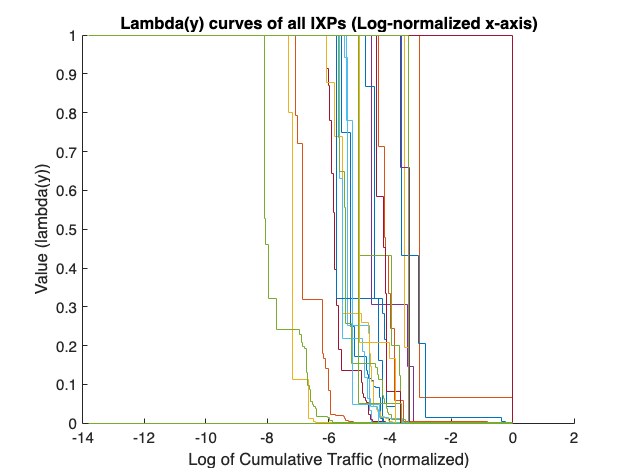

% Assuming 'data' is a table or structure with fields 'ix_id', 'd_ij', and 'b_ij_split'

% Extract all unique IXP IDs from the data
unique_ixps = unique(data.ix_id);

% Generate distinct colors for each IXP
colors = lines(numel(unique_ixps));

% Create a new figure
figure;
hold on; % Hold on to plot all IXPs on the same figure

% A small constant to avoid taking the log of zero
epsilon = 1e-6;

% Loop through all unique IXP IDs
for i = 1:length(unique_ixps)
    ixp_id = unique_ixps(i);
    
    % Extract data for the current IXP
    ixp_data = data(data.ix_id == ixp_id, :);
    
    % Sort by d_ij in descending order and calculate the cumulative sum of b_ij
    [sorted_d_ij, sortIdx] = sort(ixp_data.d_ij, 'descend');
    sorted_b_ij = ixp_data.b_ij_split(sortIdx);
    cumsum_b_ij = cumsum(sorted_b_ij);
    
    % Normalize the cumulative sum of b_ij
    normalized_cumsum_b_ij = cumsum_b_ij / max(cumsum_b_ij);
    
    % Normalize the d_ij values and apply a logarithmic transformation
    normalized_sorted_d_ij = log(sorted_d_ij / max(sorted_d_ij) + epsilon);
    
    % Add initial points to start the curve at the beginning
    normalized_cumsum_b_ij = [0; normalized_cumsum_b_ij];
    normalized_sorted_d_ij = [min(normalized_sorted_d_ij); normalized_sorted_d_ij];
    
    % Plot the non-increasing step function and store the line handle
    h = stairs(normalized_sorted_d_ij, normalized_cumsum_b_ij, 'Color', colors(i, :));
    
    % Set the ButtonDownFcn property of the line
    h.ButtonDownFcn = {@lineClickCallback, ixp_id};
end

hold off;
xlabel('Log of Cumulative Traffic (normalized)');
ylabel('Value (lambda(y))');
title('Lambda(y) curves of all IXPs (Log-normalized x-axis)');


% Callback function for clicking a line
function lineClickCallback(src, event, ixp_id)
    msgbox(['You clicked on IXP ID: ', num2str(ixp_id)]);
end











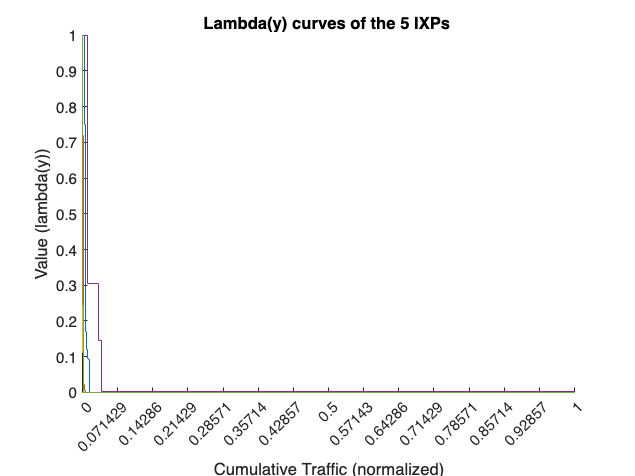

unique_ixps = unique(data.ix_id);
colors = lines(numel(unique_ixps)); % Generate distinct colors for each IXP

figure; % Create a new figure
hold on; % Hold on to plot all IXPs on the same figure

% A small constant to avoid taking the log of zero (not used here if not applying log)
epsilon = 1e-6;

legend_labels = {}; % Initialize legend labels

for i = 1:5
    ixp_id = unique_ixps(i);

    % Extract data for the current IXP
    ixp_data = data(data.ix_id == ixp_id, :);

    % Sort by d_ij in descending order and calculate the cumulative sum of b_ij
    [sorted_d_ij, sortIdx] = sort(ixp_data.d_ij, 'descend');
    sorted_b_ij = ixp_data.b_ij_split(sortIdx);
    cumsum_b_ij = cumsum(sorted_b_ij);

    % Normalize the cumulative sum of b_ij
    normalized_cumsum_b_ij = cumsum_b_ij / max(cumsum_b_ij);

    % Normalize the d_ij values and scaling from 0 to 1 directly
    normalized_sorted_d_ij = sorted_d_ij / max(sorted_d_ij);

    % Add initial points to start the curve at the beginning
    normalized_cumsum_b_ij = [0; normalized_cumsum_b_ij];
    normalized_sorted_d_ij = [0; normalized_sorted_d_ij];  % Ensure starting from 0

    % Plot the non-increasing step function
    stairs(normalized_sorted_d_ij, normalized_cumsum_b_ij, 'Color', colors(i, :));

    % Store legend label
    legend_labels{i} = ['IXP ' num2str(ixp_id)];
end

% Set custom tick marks to represent the normalized values from 0 to 1
xticks = linspace(0, 1, 15);  % Evenly spaced ticks from 0 to 1
xticklabels = linspace(0, 1, 15);  % Matching labels from 0 to 1

% Apply the custom tick marks and labels
set(gca, 'XTick', xticks, 'XTickLabel', arrayfun(@num2str, xticklabels, 'UniformOutput', false));

hold off;
xlabel('Cumulative Traffic (normalized)');
ylabel('Value (lambda(y))');
title('Lambda(y) curves of the 5 IXPs ');
% Set the x-axis limits from 0 to 1
xlim([0, 1]);
ylim([0, 1]);

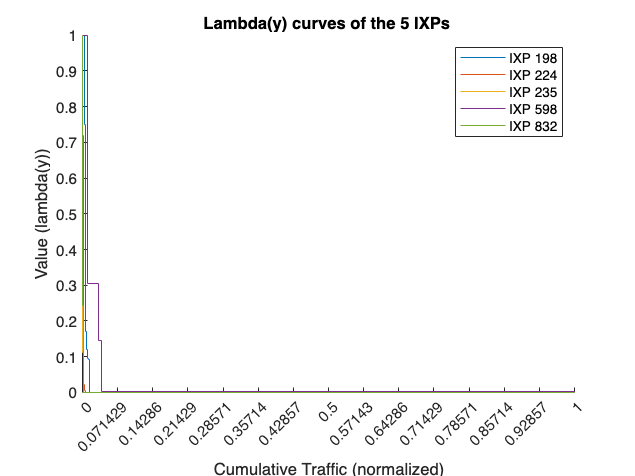


% Add legend
legend(legend_labels);

for i = 1:5
    % Extract and normalize data for the current IXP
    ixp_data = data(data.ix_id == unique_ixps(i), :);
    sorted_d_ij = sort(ixp_data.d_ij, 'ascend');  % Ensure it's sorted in ascending order
    cumsum_b_ij = cumsum(ixp_data.b_ij_split);
    normalized_cumsum_b_ij = cumsum_b_ij / max(cumsum_b_ij);

    % Normalize d_ij values
    normalized_sorted_d_ij = sorted_d_ij / max(sorted_d_ij);

    % Ensure uniqueness in ixp_data_y for interp1
    [ixp_data_y, unique_idx] = unique(normalized_sorted_d_ij);
    ixp_data_lambda = normalized_cumsum_b_ij(unique_idx);

    % Define the model function
    modelFun = @(y) C * y.^n;

    % Define the error function for minimization
    errorFun = @(y) sum((modelFun(y) - interp1(ixp_data_y, ixp_data_lambda, y, 'linear', 'extrap')).^2);

    % Perform optimization
    options = optimset('Display', 'off');
    [opt_y, err_val] = fminbnd(errorFun, 0, 1, options);

    optimal_y(i) = opt_y;
    errors(i) = err_val;
end

% Constants
n = 3; % Example: set appropriately
C = n + 1;

% Prepare to store normalized and de-normalized y values
normalized_y_values = zeros(1, 5);
denormalized_y_values = zeros(1, 5);

% Loop over each IXP
for i = 1:5
    % Extract data for the current IXP
    ixp_data = data(data.ix_id == unique_ixps(i), :);
    sorted_d_ij = sort(ixp_data.d_ij, 'ascend'); % Ensure ascending order for interpolation
    cumsum_b_ij = cumsum(ixp_data.b_ij_split);
    max_b_ij = max(cumsum_b_ij); % Maximum B_ij for current IXP
    normalized_cumsum_b_ij = cumsum_b_ij / max_b_ij;

    [ixp_data_y, unique_idx] = unique(sorted_d_ij / max(sorted_d_ij)); % Ensure unique and normalized
    ixp_data_lambda = normalized_cumsum_b_ij(unique_idx);

    % Define the model function
    modelFun = @(y) C * y.^n;

    % Error function to minimize
    errorFun = @(y) sum((modelFun(y) - interp1(ixp_data_y, ixp_data_lambda, y, 'linear', 'extrap')).^2);

    % Optimization to find the best y
    options = optimset('Display', 'off');
    [opt_y, err_val] = fminbnd(errorFun, 0, 1, options);

    % Store normalized y value
    normalized_y_values(i) = opt_y;

    % De-normalize y value using max_b_ij
    denormalized_y_values(i) = opt_y * max_b_ij;
end

% Display results
disp('Normalized y values:');

Normalized y values:


disp(normalized_y_values);

    0.5765    0.6288    0.5416    0.4981    0.6046



disp('De-normalized y values:');

De-normalized y values:


disp(denormalized_y_values);

    0.7095    0.6841    0.2501    0.0281    0.5774



% Values of n to evaluate
% Constants
n_values = [2, 3, 4]; % Values of n to iterate over

% Number of IXPs
numIXPs = length(unique_ixps);

results = table('Size', [0, 5], ...
                'VariableTypes', {'double', 'string', 'double', 'double', 'double'}, ...
                'VariableNames', {'IXP_ID', 'IXP_Name', 'n', 'Normalized_y_e', 'Normalized_y_p'});

% Loop over each IXP
for i = 1:numIXPs
    ixp_id = unique_ixps(i);
    try
        % Extract data for the current IXP
        ixp_data = data(data.ix_id == ixp_id, :);
        if isempty(ixp_data)
            continue; % Skip if no data available
        end
        
        sorted_d_ij = sort(ixp_data.d_ij, 'ascend');
        cumsum_b_ij = cumsum(ixp_data.b_ij_split);
        max_b_ij = max(cumsum_b_ij);
        normalized_cumsum_b_ij = cumsum_b_ij / max_b_ij;

        [ixp_data_y, unique_idx] = unique(sorted_d_ij / max(sorted_d_ij));
        ixp_data_lambda = normalized_cumsum_b_ij(unique_idx);

        for n = n_values
            C = n + 1; % Calculate C based on current n

            % Define the model functions
            modelFun_e = @(y) C * y.^n; % C * y^n
            modelFun_p = @(y) y.^n;     % y^n

            % Error functions to minimize
            errorFun_e = @(y) sum((modelFun_e(y) - interp1(ixp_data_y, ixp_data_lambda, y, 'linear', 'extrap')).^2);
            errorFun_p = @(y) sum((modelFun_p(y) - interp1(ixp_data_y, ixp_data_lambda, y, 'linear', 'extrap')).^2);

            % Optimization to find the best y values
            options = optimset('Display', 'off');
            [opt_y_e, err_val_e] = fminbnd(errorFun_e, 0, 1, options);
            [opt_y_p, err_val_p] = fminbnd(errorFun_p, 0, 1, options);

            % Append results for each n
            newRow = {ixp_id, ixp_data.name(1), n, opt_y_e, opt_y_p};
            results = [results; newRow];
        end
    catch ME
        warning(['Failed processing IXP ID: ', num2str(ixp_id), '. Error: ', ME.message]);
        continue; % Skip to next IXP on error
    end
end


% Display results table
disp(results);

    IXP_ID                      IXP_Name                      n    Normalized_y_e    Normalized_y_p
    ______    ____________________________________________    _    ______________    ______________

      198     "NIXI Delhi"                                    2         0.5054            0.98381  
      198     "NIXI Delhi"                                    3        0.57646            0.99276  
      198     "NIXI Delhi"                                    4        0.62568            0.99533  
      224     "NIXI Mumbai"                                   2        0.57546            0.99993  
      224     "NIXI Mumbai"                                   3        0.62876            0.99993  
      224     "NIXI Mumbai"                                   4        0.66788            0.99993  
      235     "NIXI Chennai" 


% Save the results to an Excel file
filename = 'IXP_ye_yp_values_per_n.xlsx';
writetable(results, filename);

disp(['Results saved to ', filename]);

Results saved to IXP_ye_yp_values_per_n.xlsx


% Here we go
% Constants
n_values = [2, 3, 4]; % Values of n to iterate over

% Number of IXPs
numIXPs = length(unique_ixps);

% Prepare to store results in a table
results = table('Size', [0, 5], ...
                'VariableTypes', {'double', 'string', 'double', 'double', 'double'}, ...
                'VariableNames', {'IXP_ID', 'IXP_Name', 'n', 'Normalized_y_e', 'Normalized_y_p'});


% Loop over each IXP
for i = 1:numIXPs
    ixp_id = unique_ixps(i);
    try
        % Extract data for the current IXP
        ixp_data = data(data.ix_id == ixp_id, :);
        if isempty(ixp_data)
            continue; % Skip if no data available
        end
        
        sorted_d_ij = sort(ixp_data.d_ij, 'ascend');
        cumsum_b_ij = cumsum(ixp_data.b_ij_split);
        max_b_ij = max(cumsum_b_ij);
        normalized_cumsum_b_ij = cumsum_b_ij / max_b_ij;

        [ixp_data_y, unique_idx] = unique(sorted_d_ij / max(sorted_d_ij));
        ixp_data_lambda = normalized_cumsum_b_ij(unique_idx);

        for n = n_values
            C = n + 1; % Calculate C based on current n

            % Define the model functions
            modelFun_e = @(y) C * y.^n; % C * y^n
            modelFun_p = @(y) y.^n;     % y^n

            % Error functions to minimize
            errorFun_e = @(y) sum((modelFun_e(y) - interp1(ixp_data_y, ixp_data_lambda, y, 'linear', 'extrap')).^2);
            errorFun_p = @(y) sum((modelFun_p(y) - interp1(ixp_data_y, ixp_data_lambda, y, 'linear', 'extrap')).^2);

            % Optimization to find the best y values
            options = optimset('Display', 'off');
            [opt_y_e, err_val_e] = fminbnd(errorFun_e, 0, 1, options);
            [opt_y_p, err_val_p] = fminbnd(errorFun_p, 0, 1, options);

            % Ensure y_p is the max and y_e is the min
            if opt_y_p < opt_y_e
                [opt_y_p, opt_y_e] = deal(opt_y_e, opt_y_p); % Swap if out of order
            end

            % Append results for each n
            newRow = {ixp_id, ixp_data.name(1), n, opt_y_e, opt_y_p};
            results = [results; newRow];
        end
    catch ME
        warning(['Failed processing IXP ID: ', num2str(ixp_id), '. Error: ', ME.message]);
        continue; % Skip to next IXP on error
    end
end


% Display results table
disp(results);

    IXP_ID                      IXP_Name                      n    Normalized_y_e    Normalized_y_p
    ______    ____________________________________________    _    ______________    ______________

      198     "NIXI Delhi"                                    2          0.5054          0.98381   
      198     "NIXI Delhi"                                    3         0.57646          0.99276   
      198     "NIXI Delhi"                                    4         0.62568          0.99533   
      224     "NIXI Mumbai"                                   2         0.57546          0.99993   
      224     "NIXI Mumbai"                                   3         0.62876          0.99993   
      224     "NIXI Mumbai"                                   4         0.66788          0.99993   
      235     "NIXI Chennai" 


% Save the results to an Excel file
filename = 'IXP_ye_yp_values_per_n.xlsx';
writetable(results, filename);

disp(['Results saved to ', filename]);

Results saved to IXP_ye_yp_values_per_n.xlsx




% Constants
beta_range = 1:5;  % Beta values from 1 to 5
n_values = [2, 3, 4, 5, 6, 7, 8];  % Values of n

% Prepare figure for plotting
figure;
hold on;

% Process each n value
for n = n_values
    y_p_values = [];
    ixp_count = 0;

    % Loop over each IXP to calculate y_p
    for i = 1:length(unique_ixps)
        % Load IXP data
        ixp_data = data(data.ix_id == unique_ixps(i), :);
        sorted_d_ij = sort(ixp_data.d_ij, 'ascend');
        cumsum_b_ij = cumsum(ixp_data.b_ij_split);
        
        % Normalize the data
        max_b_ij = max(cumsum_b_ij);
        if max_b_ij == 0 || any(isnan(sorted_d_ij)) || any(isinf(sorted_d_ij)) || any(isnan(cumsum_b_ij)) || any(isinf(cumsum_b_ij))
            fprintf('Skipping IXP ID %d due to invalid data.\n', unique_ixps(i));
            continue;
        end
        normalized_cumsum_b_ij = cumsum_b_ij / max_b_ij;
        [ixp_data_y, unique_idx] = unique(sorted_d_ij / max(sorted_d_ij));
        ixp_data_lambda = normalized_cumsum_b_ij(unique_idx);

        if length(ixp_data_y) < 2 % Ensure enough points for interpolation
            fprintf('Not enough data points after filtering for IXP ID %d.\n', unique_ixps(i));
            continue;
        end

        % Define the model function
        modelFun = @(y) (n+1) * y.^n;

        % Define and solve the optimization problem
        errorFun = @(y) sum((modelFun(y) - interp1(ixp_data_y, ixp_data_lambda, y, 'linear', 'extrap')).^2);
        options = optimset('Display', 'off', 'TolX', 1e-6);
        try
            [opt_y, err_val] = fminbnd(errorFun, 0, 1, options);
            y_p_values(end+1) = opt_y; % Collect valid results
            ixp_count = ixp_count + 1;
        catch ME
            fprintf('Error at IXP ID %d: %s\n', unique_ixps(i), ME.message);
        end
    end

    if ixp_count == 0
        warning('No valid IXPs processed for n = %d. Skipping plot.', n);
        continue;
    end

    % Calculate average y and PoA
    y_avg = mean(y_p_values);
    PoA = 2 * beta_range / y_avg;

    % Plot results
    plot(beta_range, PoA, '-o', 'DisplayName', sprintf('n = %d', n));
end

Skipping IXP ID 2341 due to invalid data.


Not enough data points after filtering for IXP ID 3463.


Skipping IXP ID 3548 due to invalid data.
Skipping IXP ID 4007 due to invalid data.
Skipping IXP ID 2341 due to invalid data.


Not enough data points after filtering for IXP ID 3463.


Skipping IXP ID 3548 due to invalid data.
Skipping IXP ID 4007 due to invalid data.
Skipping IXP ID 2341 due to invalid data.


Not enough data points after filtering for IXP ID 3463.


Skipping IXP ID 3548 due to invalid data.
Skipping IXP ID 4007 due to invalid data.
Skipping IXP ID 2341 due to invalid data.


Not enough data points after filtering for IXP ID 3463.


Skipping IXP ID 3548 due to invalid data.
Skipping IXP ID 4007 due to invalid data.
Skipping IXP ID 2341 due to invalid data.


Not enough data points after filtering for IXP ID 3463.


Skipping IXP ID 3548 due to invalid data.
Skipping IXP ID 4007 due to invalid data.
Skipping IXP ID 2341 due to invalid data.


Not enough data points after filtering for IXP ID 3463.


Skipping IXP ID 3548 due to invalid data.
Skipping IXP ID 4007 due to invalid data.
Skipping IXP ID 2341 due to invalid data.


Not enough data points after filtering for IXP ID 3463.


Skipping IXP ID 3548 due to invalid data.
Skipping IXP ID 4007 due to invalid data.


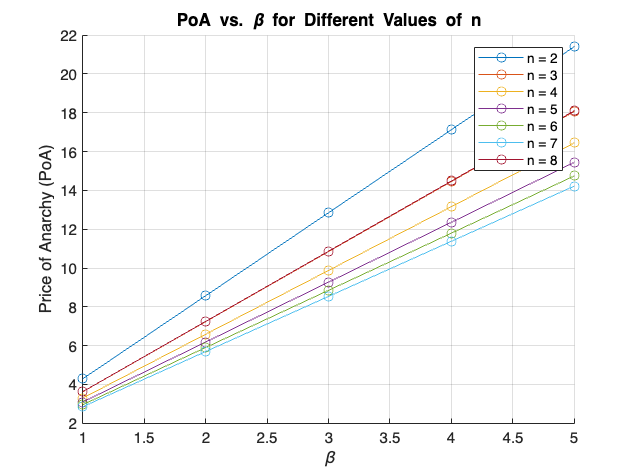


% Customize and finalize plot
xlabel('\beta');
ylabel('Price of Anarchy (PoA)');
title('PoA vs. \beta for Different Values of n');
legend show;
grid on;
hold off;

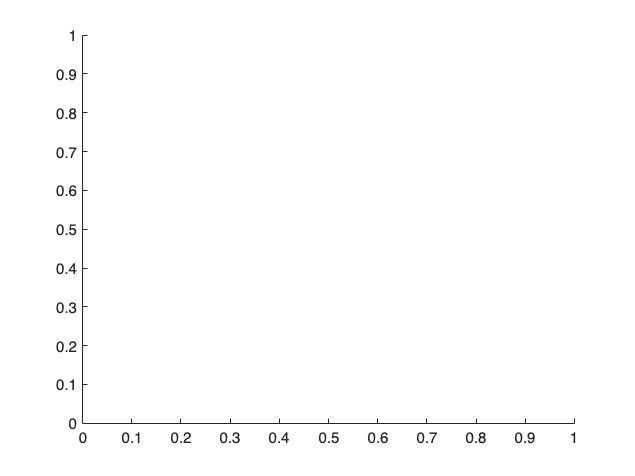

% Constants
beta_range = 1:5;  % Beta values from 1 to 5
n_values = 2:6;    % Values of n

% Load the total switch capacities for IXPs from an Excel file
% filename = 'IXPs Switch Capacity Data IN 20240503.xlsx';
filename_ = '/MATLAB Drive/BTP/IXPs Switch Capacity Data IN 20240503.xlsx';
ixp_capacity_data = readtable(filename_);

% Prepare figure for plotting
figure;
hold on;


for n = n_values
    % Array to store mean U values for each beta for the current n
    mean_U_values = zeros(length(beta_range), 1);

    % Loop over each beta
    for beta_idx = 1:length(beta_range)
        beta = beta_range(beta_idx);
        U_values = zeros(height(ixp_capacity_data), 1);

        % Calculate U for each IXP
        for i = 1:height(ixp_capacity_data)
            try
                % Extract normalized data for the current IXP, assumed prepared in advance
                ixp_id = ixp_capacity_data.ix_id(i);
                ixp_data = loadIXPData(data, ixp_id); % Function to load data for IXP, you must implement it

                % Calculate ye using the calculate_ye function
                y_e = calculate_ye(beta, n, ixp_data.normalized_sorted_d_ij, ixp_data.normalized_cumsum_b_ij);
                mu = ixp_capacity_data.total_speed_ixp(i);
                U_values(i) = y_e / mu; % Calculate Utilization Factor
            catch ME
                warning('skipping %d',i);

        end

        % Compute the mean U for the current beta
        U_values_per_n(beta_idx) = mean(U_values, 'omitnan');
    end

    % Plot results for this n
    plot(beta_range, U_values_per_n, '-o', 'DisplayName', sprintf('n = %d', n));
    end
end

Error using plot
Specify the coordinates as vectors or matrices of the same size, or as a vector and a matrix that share the same length in at least one dimension.



% Customize and finalize plot
xlabel('\beta');
ylabel('Mean Utilization Factor (U)');
title('Utilization Factor vs. Beta for Different Values of n');
legend show;
grid on;
hold off;






% Constants
beta_range = 1:5;  % Beta values from 1 to 5
n_values = 2:6;    % Values of n

% Load the total switch capacities for IXPs from an Excel file
filename = '/MATLAB Drive/BTP/IXPs Switch Capacity Data IN 20240503.xlsx';
ixp_capacity_data = readtable(filename);

% Prepare figure for plotting
figure;
hold on;

% Loop over each value of n
for n = n_values
    % Array to store mean U values for each beta for the current n
    mean_U_values = zeros(length(beta_range), 1);

    % Loop over each value of beta
    for beta_idx = 1:length(beta_range)
        beta = beta_range(beta_idx);
        U_values = zeros(height(ixp_capacity_data), 1);  % Initialize an array to store U values for each IXP

        % Calculate U for each IXP
        for i = 1:height(ixp_capacity_data)
            try
                % Extract normalized data for the current IXP
                ixp_id = ixp_capacity_data.ix_id(i);
                ixp_data = loadIXPData(data, ixp_id);  % Ensure this function is properly defined to fetch required data

                % Calculate ye using the calculate_ye function
                y_e = calculate_ye(beta, n, ixp_data.normalized_sorted_d_ij, ixp_data.normalized_cumsum_b_ij);
                mu = ixp_capacity_data.total_speed_ixp(i);
                U_values(i) = y_e / mu;  % Calculate Utilization Factor
            catch ME
                fprintf('Skipping IXP ID %d due to error: %s\n', ixp_id, ME.message);
                continue;  % Skip to the next IXP on error
            end
        end

        % Compute the mean U for this beta
        mean_U_values(beta_idx) = mean(U_values, 'omitnan');  % Calculate mean, ignoring NaNs
    end

    % Plot results for this n
    plot(beta_range, mean_U_values, '-o', 'DisplayName', sprintf('n = %d', n));
end

% Customize and finalize plot
xlabel('\beta');
ylabel('Mean Utilization Factor (U)');
title('Utilization Factor vs. Beta for Different Values of n');
legend show;
grid on;
hold off;
% New Code
beta_range = linspace(1, 5, 100);  % More fine-grained beta range for plotting
n_values = 2:6;  % Values of n

% Load data, assumed pre-loaded into 'ixp_capacity_data'

% Prepare figure for plotting
figure;
hold on;

% Loop over each value of n
for n = n_values
    % Initialize an array of function handles, one per IXP
    y_e_functions = arrayfun(@(x) @(beta) NaN, 1:height(ixp_capacity_data), 'UniformOutput', false);

    % Calculate y_e as a function of beta for each IXP
    for i = 1:height(ixp_capacity_data)

        try
            ixp_id = ixp_capacity_data.ix_id(i);
            ixp_data = loadIXPData(data, ixp_id);  % Make sure this function now properly handles your data
            y_e_functions{i} = calculate_ye(n, ixp_data.normalized_sorted_d_ij, ixp_data.normalized_cumsum_b_ij);
        catch ME
            fprintf('Skipping IXP ID %d due to error: %s\n', ixp_id, ME.message);
            continue;  % Skip to the next IXP on error
        end
    end

    % Evaluate these functions at each point in beta_range and compute mean
    U_values = zeros(size(beta_range));
    for idx = 1:length(beta_range)
        beta = beta_range(idx);
        current_betas = cellfun(@(func) func(beta), y_e_functions);
        U_values(idx) = mean(current_betas, 'omitnan');  % Compute mean, ignoring NaNs
    end

    % Plot the resulting function for this n
    plot(beta_range, U_values, '-o', 'DisplayName', sprintf('n = %d', n));
end

% Customize and finalize plot
xlabel('\beta');
ylabel('Mean Utilization Factor (U)');
title('Utilization Factor U vs. Beta for Different Values of n');
legend show;
grid on;
hold off;


% Constants
beta_range = linspace(1, 5, 100);  % Fine-grained beta range
n_values = 2:6;  % Values of n

% Load the total switch capacities for IXPs from an Excel file
filename = '/MATLAB Drive/BTP/IXPs Switch Capacity Data IN 20240503.xlsx';
ixp_capacity_data = readtable(filename);

% Prepare figure for plotting
figure;
hold on;
all_U_values = []
% Loop over each value of n
for n = n_values
    U_values_per_n = zeros(size(beta_range));  % Initialize to zero

    % Loop over each value of beta
    for beta_idx = 1:length(beta_range)
        beta = beta_range(beta_idx);
        U_values = [];

        % Calculate U for each IXP
        for i = 1:height(ixp_capacity_data)
            ixp_id = ixp_capacity_data.ix_id(i);
            ixp_data = loadIXPData(data, ixp_id);  % Ensure this function loads the required data
            y_e_func = calculate_ye(n, ixp_data.normalized_sorted_d_ij, ixp_data.normalized_cumsum_b_ij);
            y_e = y_e_func(beta);
            mu = ixp_capacity_data.total_speed_ixp(i);

            if isnan(y_e) || mu == 0
                continue;  % Skip this IXP if y_e could not be calculated or mu is zero
            end

            U = y_e / mu;
            U_values = [U_values, U];  % Collect U value
        end

        U_values_per_n(beta_idx) = mean(U_values, 'omitnan');  % Calculate mean, ignoring NaNs
        all_U_values = [all_U_values, U_values_per_n(beta_idx)];  % Collect for normalization
    end

    % Normalize U values by the maximum value found
    max_U = max(all_U_values);
    normalized_U_values_per_n = U_values_per_n / max_U;

    % Plot the normalized results for this n
    plot(beta_range, normalized_U_values_per_n, '-o', 'DisplayName', sprintf('n = %d', n));
end

xlabel('\beta');
ylabel('Utilization Factor (U)');
title('Utilization Factor U vs. Beta for Different Values of n');
legend show;
grid on;
hold off;
